# **Task_01:**   Explore the 3-dof Spring Mass damper shown below

## Objectives:

- Define our **Model parameter**s values

- Do a **Modal analysis **of the 3-dof system and compute it's UNdamped natural modes

- View the **Frequency Response Functions**(FRFs) for this baseline system

- Launch a Simulink file that contains a **Newtonian** derived model AND a **Simscape Multibody** model

- Excite the models with **ground patch motion** ($z_G$) excitation dialed in to **the resonant frequencies** of the system

- **compare** the Newton vs Simscape responses.

The system that we'll explore is shown below.  NOTE the following:

- We have 3 masses - $m_1 \;,m_2 \;\;,m_3$

- The degrees of freedom are - $z_1 \;,z_2 \;\;,z_3$ 

- Each dof is measured from an INERTIAL frame coinciding with the UNstretched spring positions

- We have a "ground patch" that can move -  $z_G$  

- We have 3 springs, and although they have not been drawn each spring has a damper in parallel.

- The UN stretched lengths of each spring are - $L_G \;\;,L_1 \;\;,L_2$

- Each mass is acted upon by an external force - $F_1 \;\;,F_2 \;\;,F_3$

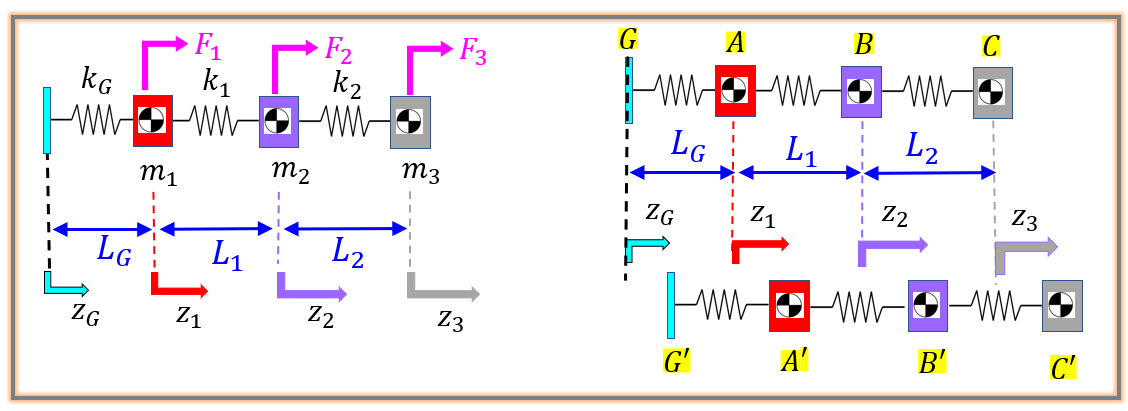

## Newton derivation of the Mechanical Equations of motion

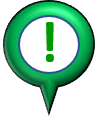The Newton 2nd Law derivation is summarized in the function file:

- [`bh_newton_smd_3dof_model_MCK.mlx`](matlab: edit bh_newton_smd_3dof_model_MCK.mlx)

## Clear your workspace

clear

## Define the Model parameters

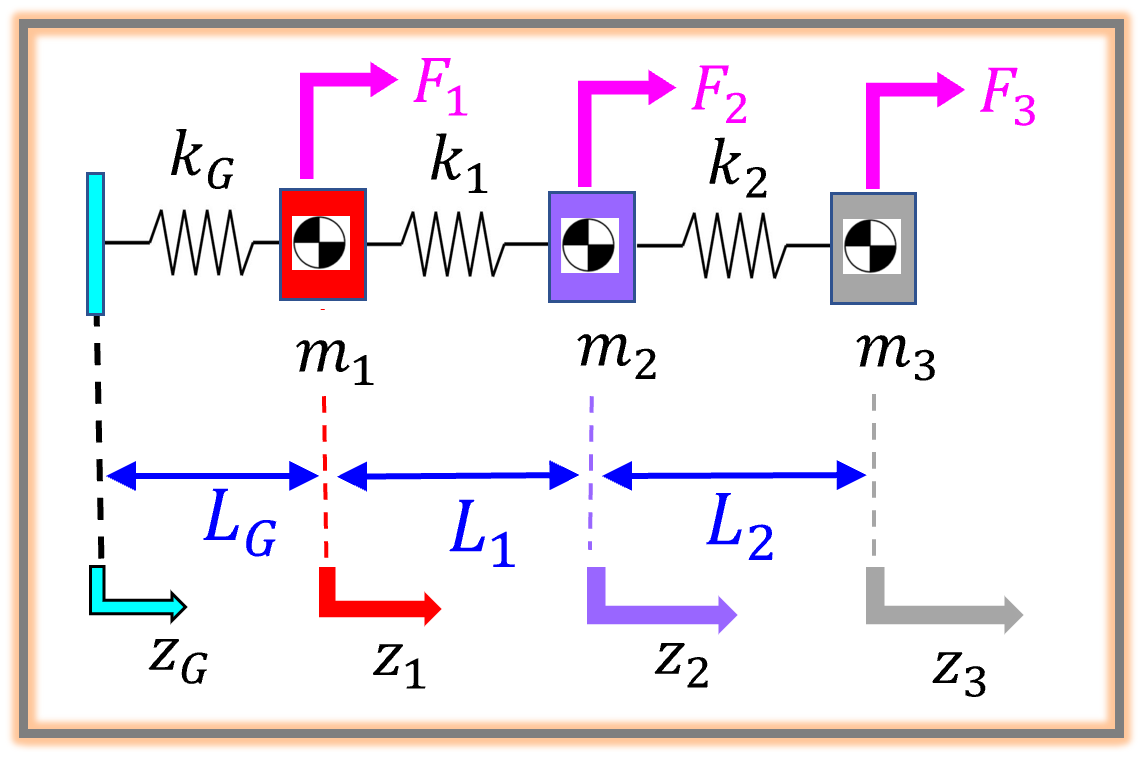

Consult a database for parameters  :

- See: [` bh_smd_3dof_tmd_params_CLS.m `](matlab:  open  bh_smd_3dof_tmd_params_CLS.m)

- See:   [`bh_smd_3dof_tmd_params_database.xlsx`](matlab:  winopen bh_smd_3dof_tmd_params_database.xlsx)

%param_DB = bh_smd_3dof_tmd_params_CLS();
%param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_2");
%param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_3");
param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_FLEX");

Masses:

params_T.m1 = param_DB.m1;  % (kg)
params_T.m2 = param_DB.m2;  % (kg)
params_T.m3 = param_DB.m3;  % (kg)

Spring Stiffness:

params_T.k1 = param_DB.k1;   % (N/m)
params_T.k2 = param_DB.k2;   % (N/m)
params_T.kG = param_DB.kG;   % (N/m)

Spring Damping:

BETA_CONST_PROP_DAMPING = 1e-3;
params_T.c1 = BETA_CONST_PROP_DAMPING*params_T.k1;    % (N/(m/s))
params_T.c2 = BETA_CONST_PROP_DAMPING*params_T.k2;    % (N/(m/s))
params_T.cG = BETA_CONST_PROP_DAMPING*params_T.kG;    % (N/(m/s))

Spring UNstretched Length:

params_T.L1 = param_DB.L1; % (m)
params_T.L2 = param_DB.L2; % (m)
params_T.LG = param_DB.LG;  % (m)

So echo our model parameters

params_T

## Initial Conditions(NEWTON)

Mass ICs

IC_Newt_T.z_col    = [0,0,0]' ;  % z1,z2,z3
IC_Newt_T.zdot_col = [0,0,0]' ;

Ground patch ICs

IC_Newt_T.zG       = 0;
IC_Newt_T.zG_dot   = 0;

## Initial Conditions(Simscape Multibody PRISMATIC joint)

In our Simscape Multibody model, we'll use [`PRISMATIC joints`](https://www.mathworks.com/help/releases/R2025b/sm/ref/prismaticjoint.html) to represent our springs

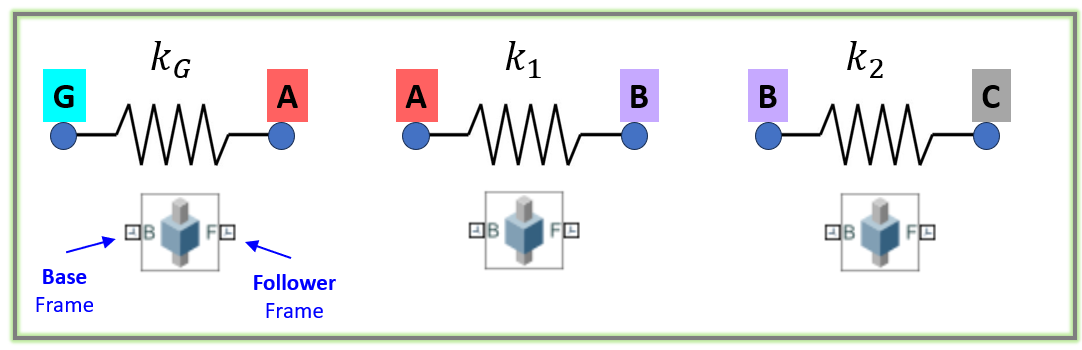

Each spring (our Prismatic joints) needs to be configured with 

- The **position** of the FOLLOWER frame relative to the BASE 

- The **velocity** of the FOLLOWER frame relative to the BASE

Which we can interpret as: 

- **POSITION**:    $\Longrightarrow$     Initial spring length 

- **VELOCITY**:    $\Longrightarrow$     Initial spring length rate of change (say velocity) 

To compute this, we'll utilize our **Newton Initial Conditions** and the **UNstretched spring lengths**

- 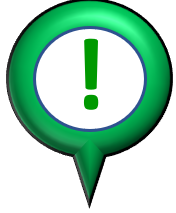 NOTE:  Simscape Multibody allows for 3D mechanical systems to be modeled ... so we need to incorporate relevant geometry parameters to cater for this. 

So, consider the following schematic:

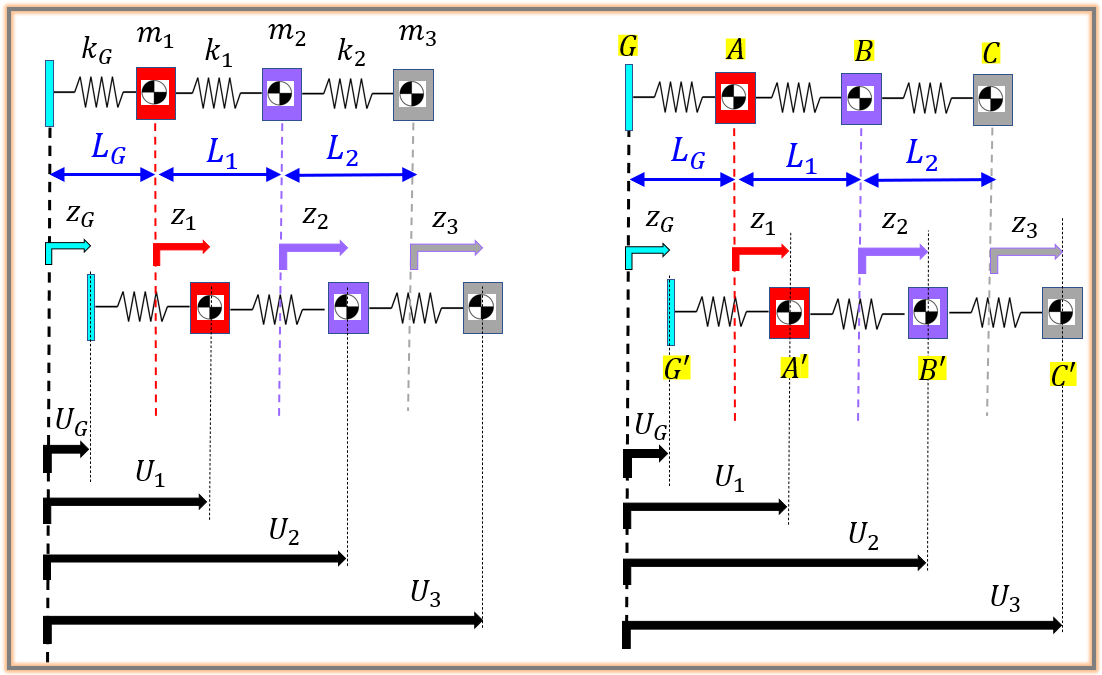

From the above figure we can write:

- 
$$U_G =z_G$$


- 
$$U_1 \;=L_G \;+z_1$$


- 
$$U_2 =L_G +L_1 +z_2$$


- 
$$U_3 =L_G \;+L_1 \;+L_2 \;+z_3$$


So the Initial Spring Lengths are:

- 
$$L_{G^{\prime } A^{\prime } } \;=\;U_1 -U_G \;=\;\left(L_G \;+z_1 \right)-\left(z_G \right)\;=\;\;L_G \;+\left(z_1 -z_G \right)$$


- 
$$L_{A^{\prime } B^{\prime } } \;=U_2 \;-U_1 \;\;=\;\left(L_G +L_1 +z_2 \right)-\left(L_G \;+z_1 \right)\;=L_1 \;+\;\left(z_2 -z_1 \right)$$


- 
$$L_{B^{\prime } C^{\prime } } \;=U_3 \;-U_2 \;\;=\;\left(L_G +L_1 +L_2 +z_3 \right)-\left(L_G \;+L_1 +z_2 \right)\;=L_2 \;+\;\left(z_3 -z_2 \right)$$


And similarly the Initial Spring Length rates of change are:

- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{G^{\prime } A^{\prime } } \right)\;=\;\;\left({\dot{z} }_1 -{\dot{z} }_G \right)$$


- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{A^{\prime } B^{\prime } } \right)\;=\;\;\left({\dot{z} }_2 -{\dot{z} }_1 \right)$$


- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{B^{\prime } C^{\prime } } \right)\;=\;\;\left({\dot{z} }_3 -{\dot{z} }_2 \right)$$


IC_PrisJ_T.springG.pos = (IC_Newt_T.z_col(1)    - IC_Newt_T.zG) + params_T.LG;
IC_PrisJ_T.springG.vel = (IC_Newt_T.zdot_col(1) - IC_Newt_T.zG_dot);

IC_PrisJ_T.spring1.pos = (IC_Newt_T.z_col(2)    - IC_Newt_T.z_col(1)) + params_T.L1;
IC_PrisJ_T.spring1.vel = (IC_Newt_T.zdot_col(2) - IC_Newt_T.zdot_col(1));

IC_PrisJ_T.spring2.pos = (IC_Newt_T.z_col(3)    - IC_Newt_T.z_col(2)) + params_T.L2;
IC_PrisJ_T.spring2.vel = (IC_Newt_T.zdot_col(3) - IC_Newt_T.zdot_col(2));

## Some Simscape visualization artifacts

I'll insert some light weight cylinders to denote the springs - this is for visualization purposes only and will have almost no effect on the system dynamics (e.g.:   mass = ${10}^{-10} \;$kg)

vis_itemT.r = 0.05 * 0.1;          %(m)
vis_itemT.L = params_T.L1/4; %(m)
params_T.m  = 1e-10;          % (kg)

# Define the System matrices for our Damped system

The mechanical equations of motion for this system have the classic form:

- $M\ldotp \ddot{Z} \;\;+\;C\ldotp \dot{Z} \;\;+\;K\ldotp Z\;\;=F$       And are defined here  [`bh_newton_smd_3dof_model_MCK.mlx`](matlab: edit bh_newton_smd_3dof_model_MCK.mlx)

So let's create some numeric matrices $M\;,C\;,K$

[M_mat, C_mat, K_mat, ~] = ...
     bh_newton_smd_3dof_model_MCK( params_T.m1, params_T.m2, params_T.m3, ...
                                   params_T.kG, params_T.k1, params_T.k2, ...
                                  "DAMPING_C", [params_T.cG, params_T.c1, params_T.c2] )

So what've we got ?

whos   M_mat  C_mat  K_mat

# Modal Analysis on the UNdamped system

Next, let's do a MODAL analysis of the system.  Consider the **UNdamped** homogeneous system:

- $M\ldotp \ddot{X} \;+\;K\ldotp X\;=0$  where $X\;\in R^{\;N\times 1}$

And let's look for a harmonic solution of the form:

- 
$$X\left(t\right)=\;\;\;\;\;\;v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$\dot{X} \left(t\right)=\;\;\;\;\;\;\;\;\;\;i\ldotp \omega \;\ldotp X\left(t\right)$$


- 
$$\ddot{X} \left(t\right)=\;\;\;-1\ldotp \omega^2 \ldotp X\left(t\right)\;$$


Then our ODE becomes:

- 
$$\left\lbrack -M\ldotp \omega^2 \;\;+\;\;K\right\rbrack \ldotp X\left(t\right)\;=\;0$$


- 
$$K\ldotp X\left(t\right)=M\ldotp X\left(t\right)\ldotp \omega^2$$


- 
$$M^{-1} \ldotp K\ldotp X\left(t\right)=\omega^2 \ldotp X\left(t\right)$$


- 
$$M^{-1} \ldotp K\ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t} =\omega^2 \ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$M^{-1} \ldotp K\ldotp v=\omega^2 \ldotp v$$


- $A\ldotp v=\lambda \;\ldotp v$       where  $\lambda =\omega^2$  and $A=M^{-1} \ldotp K$

The last equation(above) is the **classic Eigenvalue problem**, which we'll now solve

- See [`bh_newton_smd_3dof_eig.mlx`](matlab:  edit bh_newton_smd_3dof_eig.mlx)

- `w2_list   :`     a vector of the eigenvalues, i.e.:    $\omega^2$ 

- `eVec_PHI  :   `a matrix of the nomalized eigenvectors i.e.:   $I\;\;={\;\;V}^T \ldotp M\ldotp V$    and     $\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$

[w2_list, eVec_PHI] = bh_newton_smd_3dof_eig( params_T.m1, params_T.m2, params_T.m3, ...
                                              params_T.kG, params_T.k1, params_T.k2 )

### Confirm that we do indeed have normalized Eigenvectors

-   
$$I\;\;={\;\;V}^T \ldotp M\ldotp V$$


- 
$$\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$$


Im_mat      = eVec_PHI.' * M_mat * eVec_PHI;
w2_mat      = eVec_PHI.' * K_mat * eVec_PHI;

figure
tiledlayout(1,2)

nexttile
    heatmap(Im_mat, "Colormap", jet(20) );
        title("V^T . M . V")

nexttile
    heatmap(w2_mat, "Colormap", jet(50) );
        title("V^T . K . V")

### Great, so let's summarize what we have. 

Our UNdamped Natural frequencies of vibration are:   $\omega \;\;\;\left\lbrack \frac{\mathrm{rad}}{\sec }\right\rbrack$:

w_list = sqrt( diag(w2_mat) );
w_table = array2table( [w_list, w_list/(2*pi)], "VariableNames", {'w_radpersec', 'f_Hz'}  )

Our MODE shapes (normalized by our MASS matrix) are the columns of the matrix:

eVec_PHI

### To Visualize only our mode shapes

For visualization purposes, let's normalize each mode shape column by it's largest absolute value ... so that we can see (perhaps more easily ?) which DOF makes the dominant contribution in each mode 

NUM_DOF             =   size(eVec_PHI,1);
MAX_NORM_eVec_PHI   = eVec_PHI ./ repmat(max(abs(eVec_PHI)), NUM_DOF, 1);

Create a table of our **MAX Value normalized** Mode shapes:

mode_table = array2table( MAX_NORM_eVec_PHI, ...
                          "VariableNames",  "MODE_"+[1:NUM_DOF], ...
                          "RowNames"     ,  ["z1","z2","z3"] ); 

And visualize the MAX normalized Mode shapes in a HEATMAP

figure;
    heatmap( ("MODE_"+[1:NUM_DOF]), ["z1","z2","z3"], MAX_NORM_eVec_PHI, "Colormap", jet(50)  );
        title("MAX Value normalised mode shape columns")

# What do the FRFs look like for the BASELINE system

Recall our (***damped***) Mechanical system:

- $M\ldotp \ddot{X} \;\;+\;C\ldotp \dot{X} \;\;+\;K\ldotp X\;=F$     And are defined here  [`bh_newton_smd_3dof_model_MCK.mlx`](matlab: edit bh_newton_smd_3dof_model_MCK.mlx)

And our Mechanical system matrices:

 whos   M_mat  C_mat  K_mat

Create the State Space model

- $\pmatrix{
\ddot{x} \cr
\dot{x} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{P \times P} & 0_{P \times P} \cr
}$$. \pmatrix{
\dot{x} \cr
x \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}.F$

- $y=G\ldotp z\;+\;D\ldotp u$     where    $G=\;\left\lbrack \begin{array}{cc}
0_{P\times P}  & I_{P\times P} 
\end{array}\right\rbrack$    and  $D=0_{P\times P}$

    A = [   -inv(M_mat)*C_mat,    -inv(M_mat)*K_mat;  
        eye(size(M_mat,1)),    zeros(size(M_mat,1))    ];
    B = [inv(M_mat);zeros(size(M_mat,1))];
    G = [zeros(size(M_mat,1)), eye( size(M_mat,1) )];
    D = zeros( size(M_mat,1) );

    H_base_mat = ss(A,B,G,D,0,"Outputname",["z1","z2","z3"],"InputName",["f1g+f1","f2","f3"]);

    whos H_base_mat

### Plot the FRFs associated with a force applied only at mass $m_1$

Plot the FRFs where the input is $u={\left(F_1 \right)}_{\mathrm{TOTAL}} \;$

- Recall that    ${\left(F_1 \right)}_{\mathrm{TOTAL}} \;\;\;=\;\;\;F_1 \;+\;k_G \ldotp z_{G\;} \;+\;c_G \ldotp {\dot{z} }_G$

And superimpose the UNdamped Natural frequencies

    w_list_for_bode = [1:0.001:100];
    bd_opts =  bodeoptions();
    bd_opts.PhaseVisible="off";

    for kk=1:3
        figure;
            bp = bodeplot(H_base_mat(kk,1), w_list_for_bode, bd_opts);
                bp.Responses(1).LineWidth = 2;
                grid on
                title("H_{BASE}("+kk+",1)", FontWeight="bold")    

            % plot the UNdamped Natural frequencies from our MODAL analysis in pink
            hold on
            xline(w_list, "--m")
    end

# Open the Simulink and Simscape Multibody model

In the Simulink model we'll get you to **excite the system** at it's **natural/resonant frequencies**

- these natural frequencies are defined below

  w_baseline = w_list;  

Now open and run the Simulink model that contains 2 implementations of the 3-dof system

open_system("bh_sim_smd_3dof_model.slx")

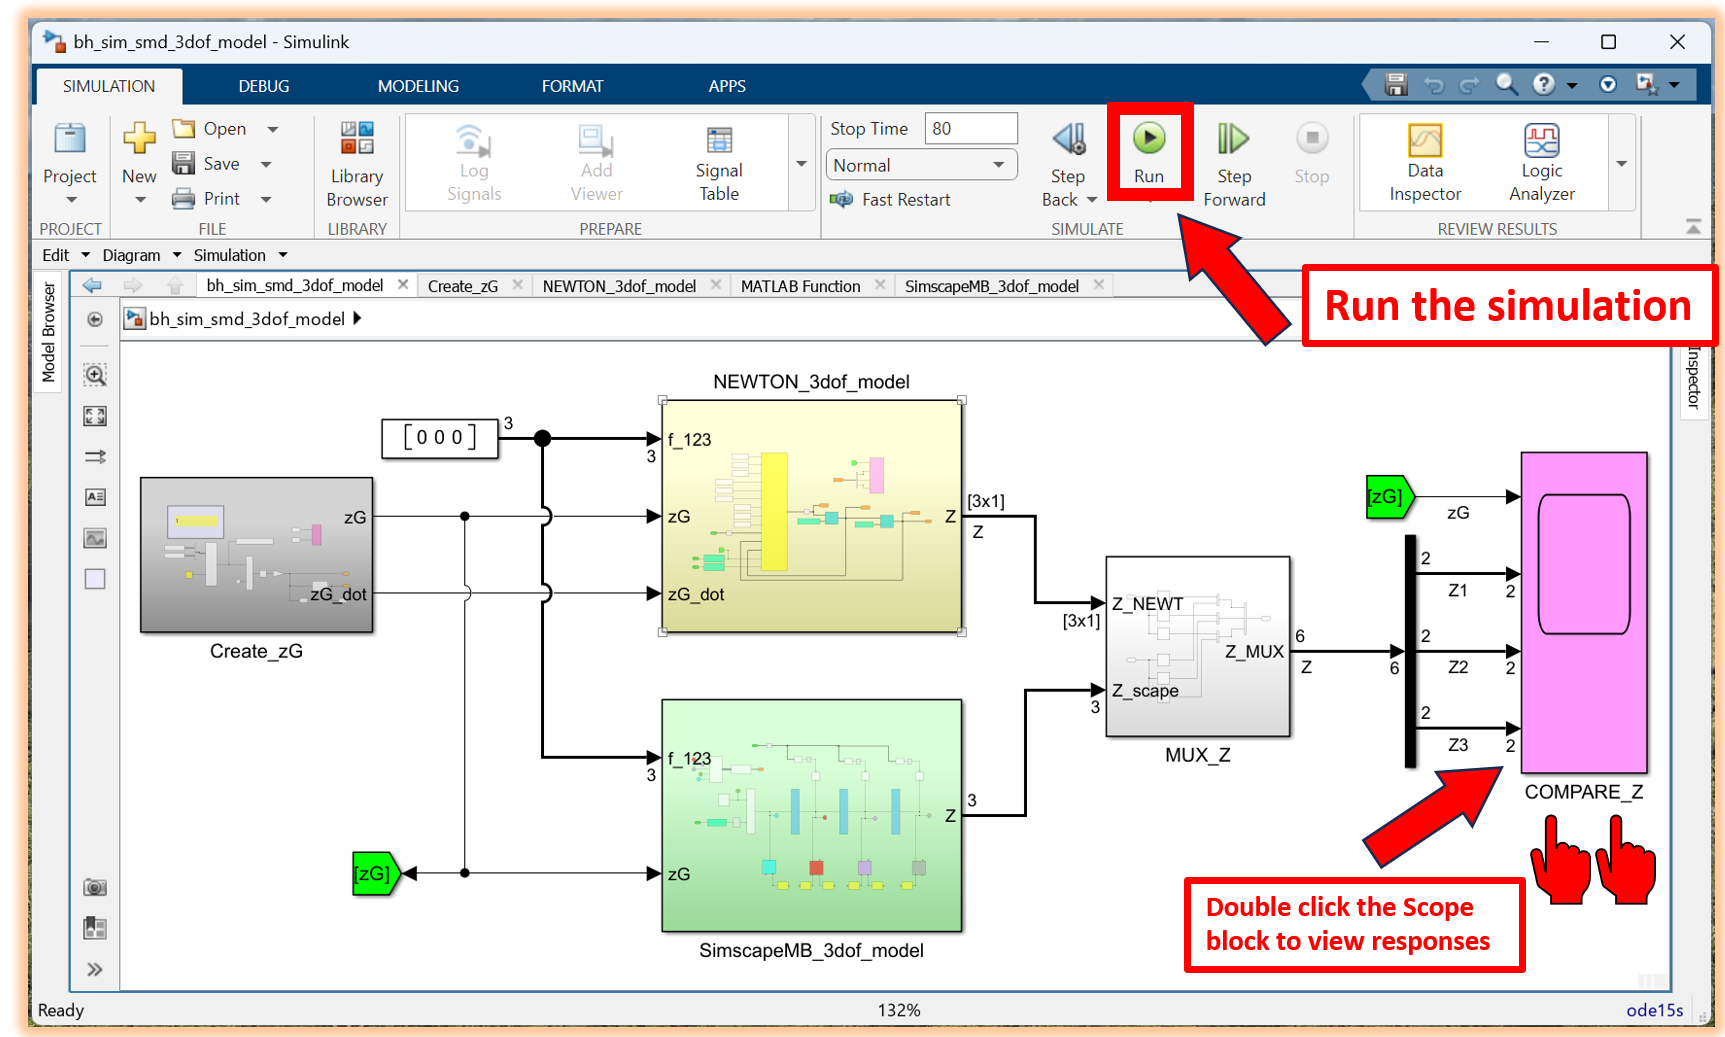

When the Simulink model opens:

- Expand the **Model Browser**

- Go to the **create_zG** subsystem

- Interact with the **YELLOW dropbox** and choose which resonance to run (e.g.:  $\left.1^{\mathrm{st}} \;,2^{\mathrm{nd}} ,3^{\mathrm{rd}\;} \right)$

- NOTE:  index choices $4^{\mathrm{th}} ,5^{\mathrm{th}} ,6^{\mathrm{th}}$ allow other excitation frequencies to be applied

- Run the Simulation and observe the structure's response